Convolution theorem

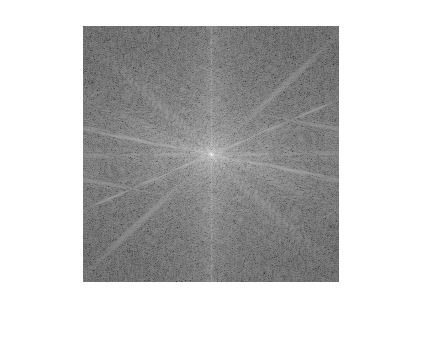

cam = imread("cameraman.tif");
sf = fftshift(fft2(cam));

fftshow(sf,'log');

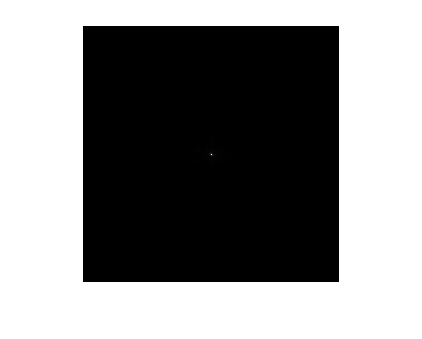

fftshow(sf,'abs');

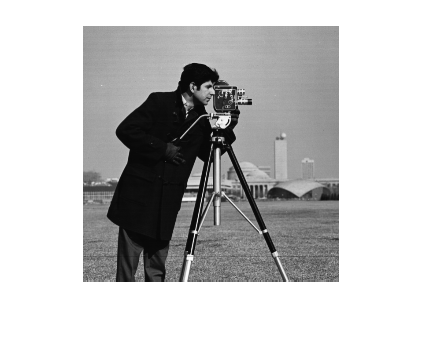

imshow(cam);

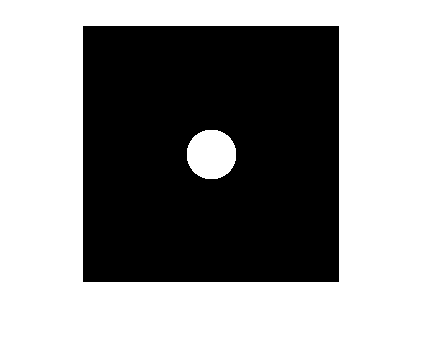

[x y] = meshgrid(-128:127,-128:127);
z= sqrt(x.^2 +y.^2);

circle= (z<25);

imshow(circle);

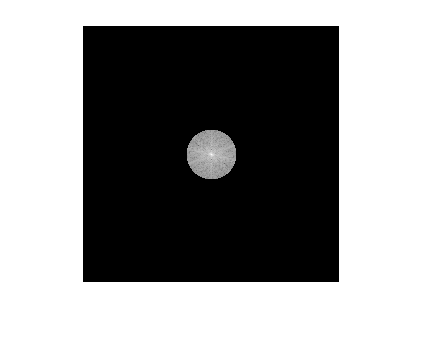


mutli = sf .* circle;

fftshow(mutli)

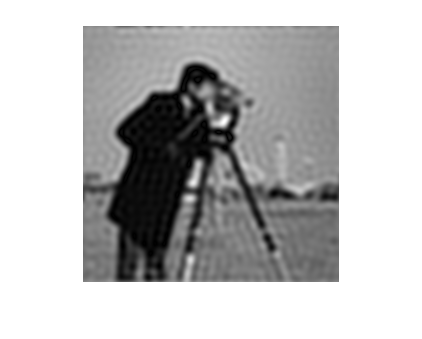

inverse_multi = ifft2(mutli);

fftshow(inverse_multi,'abs');

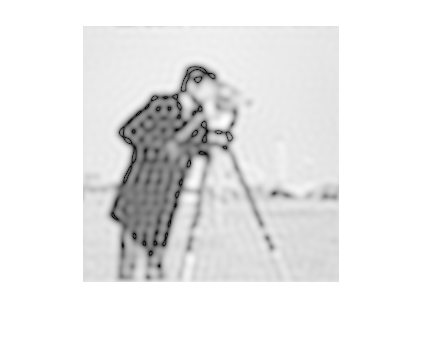

fftshow(inverse_multi,'log');